# Loading Dataset

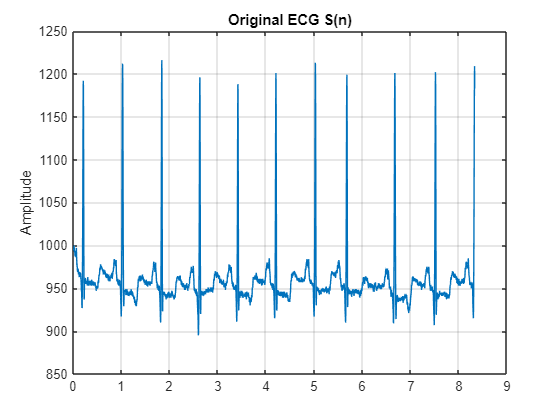

clc;
clear;
close all;
tic
%% Phase I: Initialisation
data = readmatrix('100.csv');
x = data(:,2);
% Original ECG signal S(n)
S = x;          % Use your ECG variable
N = length(S);

fs = 360;
t = (0:N-1)/fs;

figure;
plot(t(1:3000), S(1:3000))
title('Original ECG S(n)')
ylabel('Amplitude')
grid on

# Adding WGN(White Gaussian Noise)

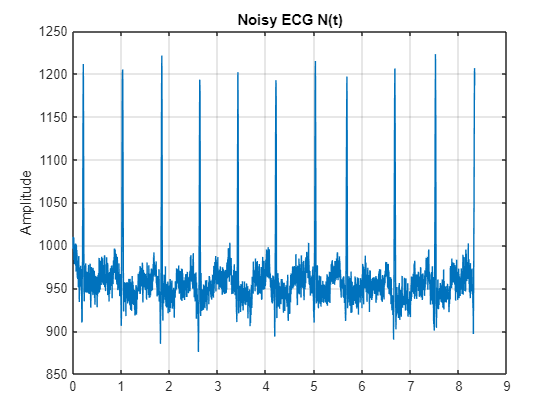

%% Add White Gaussian Noise (Equation 11)

sigma = 0.25 * std(S);
N_noisy = S + sigma * randn(size(S));

figure;
plot(t(1:3000), N_noisy(1:3000))
title('Noisy ECG N(t)')
ylabel('Amplitude')
grid on

%% Calculate SNRinput (Equation 14)
SNR_input = 10*log10(sum(S.^2) / sum((S - N_noisy).^2))

SNR_input = 39.9752

%% Wavelet denoising parameters (Table 1)

Phi_list = {'coif1','coif3','sym3','sym5','db4','db6'};
beta_list = {'s','h'};
lambda_list = {'rigrsure','sqtwolog','heursure','minimaxi'};
rho_list = {'one','sln','mln'};

L_min = 1;
L_max = 10;

%% PSO parameters (Paper)

C1 = 2;
C2 = 2;
NP = 5;        % number of WT parameters
itermax = 2;
pop_size = 50;
w = 0.7;

%% Initialise swarm

for i = 1:pop_size
    
    particle(i).Phi = randi(length(Phi_list));
    particle(i).L = randi([L_min L_max]);
    particle(i).beta = randi(2);
    particle(i).lambda = randi(length(lambda_list));
    particle(i).rho = randi(length(rho_list));
    
    velocity(i).Phi = 0;
    velocity(i).L = 0;
    velocity(i).beta = 0;
    velocity(i).lambda = 0;
    velocity(i).rho = 0;
end

%% SECTION 1: Initial fitness evaluation (Phase II)

for i = 1:pop_size
    
    % Extract parameters from particle
    Phi = Phi_list{particle(i).Phi};
    L = particle(i).L;
    beta = beta_list{particle(i).beta};
    lambda = lambda_list{particle(i).lambda};
    rho = rho_list{particle(i).rho};
    
    % Wavelet denoising (Phase III inside optimisation)
    S_hat = wden(N_noisy, lambda, beta, rho, L, Phi);
    
    % SNRoutput (Equation 15)
    SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat).^2));
    
    % Fitness (Equation 13)
    fitness(i) = SNR_output - SNR_input;
    % Local best
    pbest(i) = particle(i);
    pbest_val(i) = fitness(i);
end

% Global best (Equation 8)
[gbest_val, idx] = max(pbest_val);
gbest = particle(idx);

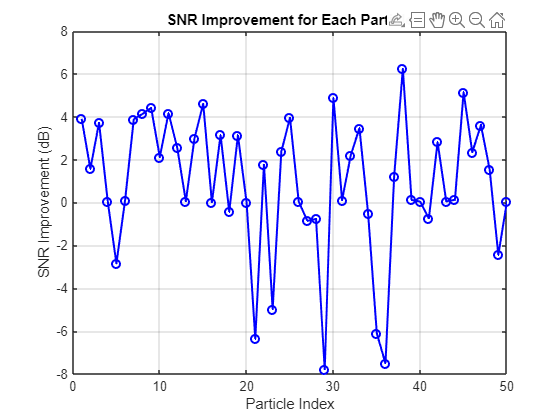

figure;
plot(1:pop_size, fitness,'bo-','LineWidth',1.5)
xlabel('Particle Index')
ylabel('SNR Improvement (dB)')
title('SNR Improvement for Each Particle')
grid on

%% PSO main loop

for iter = 1:itermax
    
    for i = 1:pop_size
        
        r1 = rand;
        r2 = rand;
        
        % Velocity update (Equation 9)
        velocity(i).L = w*velocity(i).L ...
            + C1*r1*(pbest(i).L - particle(i).L) ...
            + C2*r2*(gbest.L - particle(i).L);
        
        % Position update (Equation 10)
        particle(i).L = round(particle(i).L + velocity(i).L);
        
        % Boundary condition
        particle(i).L = max(L_min, min(L_max, particle(i).L));
        
        % Random re-initialisation for categorical variables
        particle(i).Phi = randi(length(Phi_list));
        particle(i).beta = randi(2);
        particle(i).lambda = randi(length(lambda_list));
        particle(i).rho = randi(length(rho_list));
        
        %% Evaluate again
        
        Phi = Phi_list{particle(i).Phi};
        L = particle(i).L;
        beta = beta_list{particle(i).beta};
        lambda = lambda_list{particle(i).lambda};
        rho = rho_list{particle(i).rho};
        
        S_hat = wden(N_noisy, lambda, beta, rho, L, Phi);
        
        SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat).^2));
        
        fitness(i) = SNR_output - SNR_input;
        
        % Update local best (Equation 7)
        if fitness(i) > pbest_val(i)
            pbest(i) = particle(i);
            pbest_val(i) = fitness(i);
        end
    end
    
    % Update global best
    [gbest_val, idx] = max(pbest_val);
    gbest = pbest(idx);
    
    disp(['Iteration ' num2str(iter) ...
        ' Best SNR improvement = ' num2str(gbest_val)]);
end

Iteration 1 Best SNR improvement = 6.23
Iteration 2 Best SNR improvement = 6.23


%% SECTION 2: Final WT denoising (Phase III)

Phi_opt = Phi_list{gbest.Phi};
L_opt = gbest.L;
beta_opt = beta_list{gbest.beta};
lambda_opt = lambda_list{gbest.lambda};
rho_opt = rho_list{gbest.rho};

S_hat_final = wden(N_noisy, lambda_opt, ...
    beta_opt, rho_opt, L_opt, Phi_opt);

%% Phase IV: Performance measures

% SNRoutput
SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat_final).^2));

% MSE
MSE = mean((S - S_hat_final).^2);

% RMSE
RMSE = sqrt(MSE);

% PRD
PRD = 100 * sqrt(sum((S - S_hat_final).^2) / sum(S.^2));

disp(['Final SNR = ' num2str(SNR_output)]);

Final SNR = 46.2052


disp(['PRD = ' num2str(PRD)]);

PRD = 0.48949


disp(['RMSE = ' num2str(RMSE)]);

RMSE = 4.7163


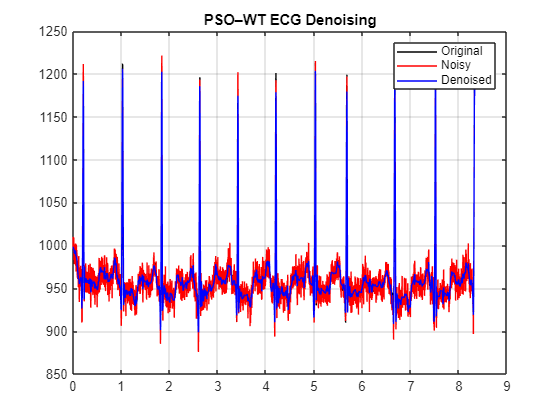

figure;
plot(t(1:3000), S(1:3000),'k'); hold on
plot(t(1:3000), N_noisy(1:3000),'r');
plot(t(1:3000), S_hat_final(1:3000),'b');
legend('Original','Noisy','Denoised')
title('PSO–WT ECG Denoising')
grid on